# Invasion Fitness under Constant Selection

The following code applies the result from Rosenbloom et al (Mutation Rate Evolution in Replicator Dynamics) that Invasion fitness of the mutation rate $u$ into a population with trait distribution $\phi(\tilde{x})$ is $\lambda_{\max}(Q(u)F(\tilde{x}))-\phi(\tilde{x})$, where

- $Q(u)$ is the "spread matrix," with $ij^{\textrm{th}$ entry the probability an individual with trait $i$ while have an offspring of trait $j$.

- $F(\vec{x})$ is the "growth matrix," which is diagonal with $ii^{\textrm{th}}$ entry the fitness of trait $i$, given $\vec{x}$.

Under constant selection, where the fitness doesn't vary with the trait distribution or time, the equilibrium distribution will simply be the eigenvector corresponding to the maximum eigenvalue, which will conveniently be the average fitness. Thus, a single graph of the maximum eigenvalues is sufficient to tell how evolution will evolve (in the direction that increases this value). 

The code has the following inputs. The first two are more significant, so are given in their own blocks, while the second appear in the main computation's block. 

- Local Mutation Kernel

- Fitness Function

- Discretization Size

- Query Mutation Rates

All the code sections can be run by pressing F5, then individual changes can be made to any of the model inputs, and the main computation can be re-executed to see how this changes the results. 

## Initialize

clear; clc; % clear stored variables
close all % closes open figures

## Local Mutation Kernel

Here we define the local mutation kernel, which govens how offspring mutate for a given mutation rate $u$. 

This also defines $Q(u)$, given by how mutation beyond the boundaries is handled. The code for this is given in functions defined at the end of the file (as Matlab requires for local functions). 

To better visualize this, some rows of $Q(u)$ are plotted. 

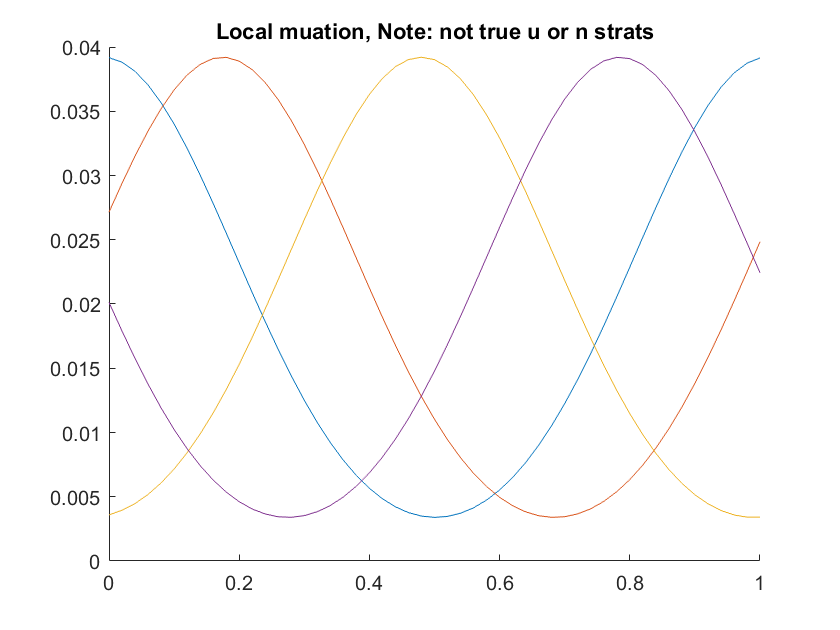

normal = @(xs, strat, u) normpdf(xs,strat,u); %exp(((xs-mean)/sigma).^2/2)/(sigma*sqrt(2*pi));
% u = sigma, the standard deviation
peak   = @(xs, strat, u) interp1([-10, strat-u/2, strat, strat+u/2, 10], [0, 0, 1, 0, 0], xs);
flat   = @(xs, strat, u) double(abs(xs-strat) < u/2);

spread_funct = normal;


handle_OoB = "circular";
if handle_OoB == "truncate"
    spread_matrix_funct = @(u,n_strats) trunc_spread_matrix(u, spread_funct, n_strats);
elseif handle_OoB == "accumulate"
    spread_matrix_funct = @(u,n_strats) accum_spread_matrix(u, spread_funct, n_strats);
elseif handle_OoB == "circular"
    spread_matrix_funct = @(u,n_strats) circ_spread_matrix(u, spread_funct, n_strats);
elseif handle_OoB == "int_accum"
    spread_matrix_funct = @(u,n_strats) integ_accum_spread_matrix(u, spread_funct, n_strats);
elseif handle_OoB == "int_trunc"
    spread_matrix_funct = @(u,n_strats) integ_trunc_spread_matrix(u, spread_funct, n_strats);
elseif handle_OoB == "int_circ"
    spread_matrix_funct = @(u,n_strats) integ_circ_spread_matrix(u, spread_funct, n_strats);
elseif handle_OoB == "unif"
    spread_matrix_funct = @(u,n_strats) unif_spread_matrix(u, spread_funct, n_strats);
elseif handle_OoB == "flat_circ"
    spread_matrix_funct = @(u,n_strats) flat_circ_spread_matrix(u,1,n_strats);
end

spread_matrix_funct = @(u,n_strats) norm_circ_spread_matrix(u,normal,n_strats);
%spread_matrix_funct = @(u,n_strats) circ_spread_matrix(u,normal,n_strats);

test_n = 51;
test_u = 0.2;
test_spread = spread_matrix_funct(test_u,test_n);
figure
hold on
to_show = [1, floor(0.2*test_n), floor(0.5*test_n), floor(0.8*test_n)];
for i=1:length(to_show)
    plot(linspace(0,1,test_n), test_spread(:, to_show(i)))
end
title("Local muation, Note: not true u or n strats")
hold off % note some are higher / lower because of normalization

## Fitness

Here we define the fitness we want to investigate. 

To help visualize this, a plot is given, though not with the true discretization. 

Some options: 

min_fit, sin_fit, cos_fit, 

twin_steps_funct(w,g,h), three_steps_funct(w,d,h), centered_two_steps_funct(w1,h1,w2,h2), peak_and_shoulders(ph, pw, vw, sh)

rand_fit_1(n_pts), and generic is @(strats) XXX.

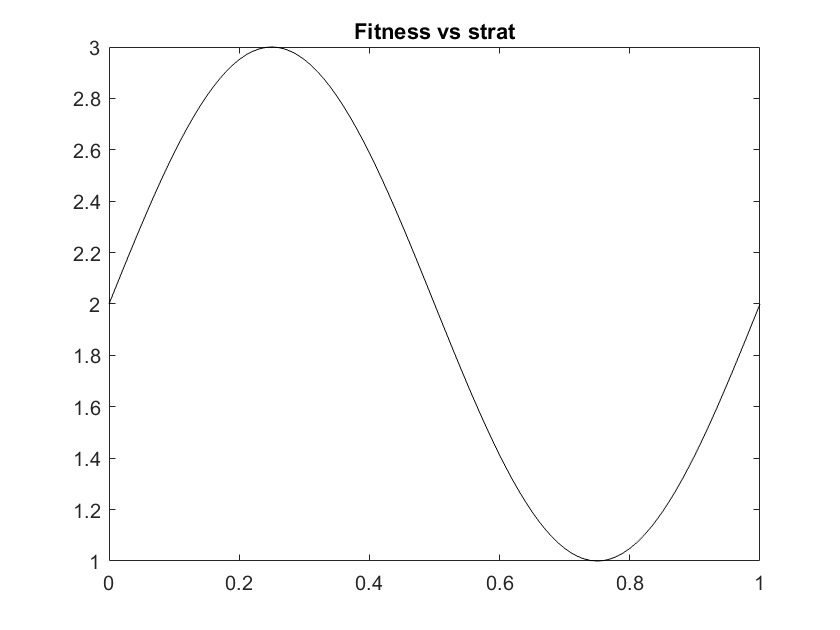

indic = @(x,a,b) x>a && x<b;

const       = @(strats) ones(size(strats));
min_fit     = @(strats) 1+min(strats, 1-strats);
sin_fit     = @(strats) 2+sin(2*pi*(strats));
cos_fit     = @(strats) 2+cos(2*pi*strats);
scrunch_sin = @(strats) arrayfun(@(x) 2+sin(6*pi*x*indic(x,1/3,2/3)), strats);
two_steps   = @(strats) arrayfun(@(x) 1+2*indic(x,0,0.2)+2.2*indic(x,1-0.025,1), strats);

twin_steps_funct = @(w,g,h) @(strats) arrayfun(@(x) ...
    1+(h-1)*indic(x,1/2-g/2-w,1/2-g/2)+(h-1)*indic(x,1/2+g/2,1/2+g/2+w), strats);
twin_steps = twin_steps_funct(0.2, 0.4, 2); % in circ?

three_steps_funct = @(w,d,h) @(strats) arrayfun(@(x) 1 + (h-1)*indic(x,0.5-d-3*w,0.5-d-w) + ...
    1*indic(x,0.5-w,0.5+w) + (h-1)*indic(x,0.5+d+w,0.5+d+3*w), strats);
three_steps = three_steps_funct(0.1, 0.05, 1.9);

centered_two_steps_funct = @(w1,h1,w2,h2) @(strats) arrayfun(@(x) ...
    1 + h1*indic(x,(1-w1-w2)/3, (1-w1-w2)/3+w1) + ...
    h2*indic(x,1-(1-w1-w2)/3-w2, 1-(1-w1-w2)/3), strats);
centered_two_steps = centered_two_steps_funct(0.2,3,0.025,3.2);

peak_and_shoulders = @(ph, pw, vw, sh) @(strats) arrayfun(@(x) ...
    sh+(ph-1)*indic(x,0.5-pw/2, 0.5+pw/2)+(1-sh)*indic(x,0.5-pw/2-vw, 0.5+pw/2+vw), strats);
foo = peak_and_shoulders(1.51,0.1,0.05,1.5);

%load('increasing with MR')
%fitness = @(t,dist) interp1(linspace(0,1,51), ...
%    fitness_leading_to_increasing_curve, strats);

fitness = "sin_fit";

if fitness{1}(1:4) == "rand" && fitness{1}(1:10) == "rand_fit_1" % short-circuits for non-rand commands
    n_pts = eval(fitness{1}(12:(end-1)));
    rand_ys = rand(1,n_pts);
    fitness = @(strats) 1+interp1(linspace(0,1,n_pts),rand_ys, strats); 
elseif fitness{1}(1:4) == "rand" && fitness{1}(1:10) == "rand_fit_2"
    n_pts = eval(fitness{1}(12:(end-1)));
    rand_xs = rand(1,n_pts);
    rand_ys = rand(1,n_pts);
    fitness = @(strats) 1+interp1(rand_xs,rand_ys, strats);
else
    fitness = eval(fitness);
end

%fitness = @(strats) 1+1*(1+cos(10*pi*strats));
%fitness = @(strats) 1+(cos(10*pi*strats)).^10;
%fitness = @(strats) square(5*2*pi*strats);

%fitness = centered_two_steps_funct(0.2,3,0.025,3.2);
a = 0.35; b = 0.65;
%fitness = @(strats) arrayfun(@(x) indic(x,0,a)+indic(x,b,1)+(2+cos(10*pi*x))*indic(x,a,b), strats);

h = 2; w = 0.4; dip = 0.1; dip_width = 0.04;
step_with_dip = @(h,w,dip,dip_width) @(strats) arrayfun(@(x) 1 + ...
    (h-1)*indic(x,1/2-w/2,1/2+w/2) - dip*indic(x,1/2-dip_width/2,1/2+dip_width/2), strats);
%fitness = step_with_dip(2,0.1,0.1,0.01);

%fitness = peak_and_shoulders(3,0.2,0.05,1.1);
%fitness = @(strats) peak(strats,0.5,0.01);

test_n = 101;
figure
plot(linspace(0,1,test_n), fitness(linspace(0,1,test_n)), 'k')
title("Fitness vs strat")

## Compute Invasion Fitness for a Given Discretization and Invadings MR's

Example us = 0.1*(1:25) or linspace(0.1, 0.2, 50)

n_strats = eval("51");
strats = linspace(0,1,n_strats);

fine   = 0.01*(1:75);
coarse = 0.1*(1:25);
small  = 0.025*(1:10); % good for sin

us = eval("0.1*(1:10)");

% "Error using eig. Input matrix contains NaN or Inf" - can occur if u is
% too small for given discretization

tic % could run in a loop, varying n_strats, spread_funct, etc.
[max_eigs, stable_dists] =  compute_max_eigs(fitness,spread_matrix_funct,us,n_strats);
toc

Elapsed time is 0.427188 seconds.


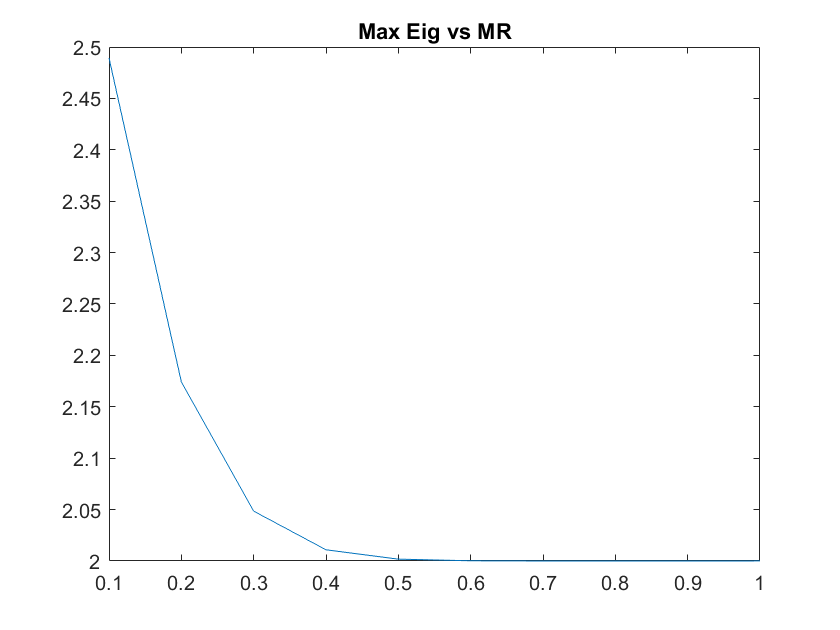

figure
plot(us, max_eigs)
title("Max Eig vs MR")

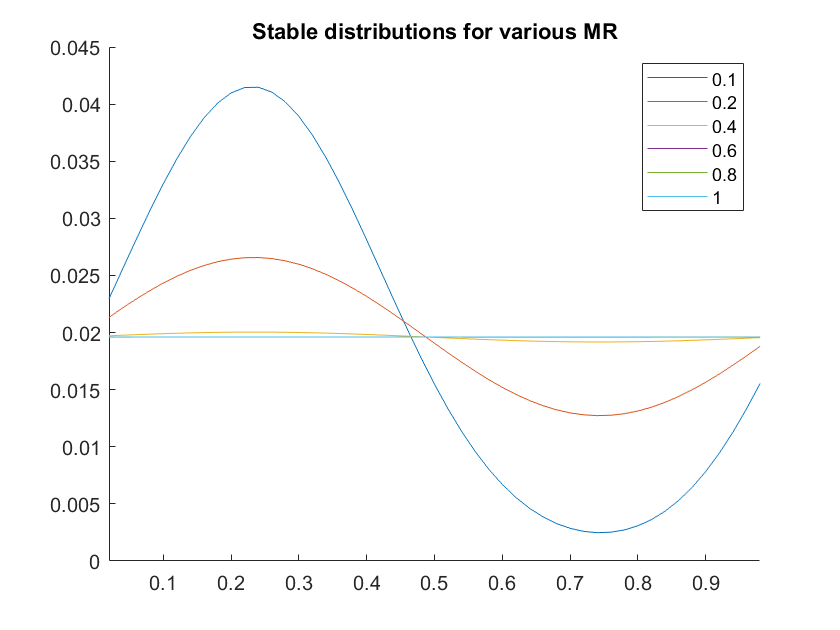

figure
hold on
n_plot = 5;
if length(us) > n_plot
    is = [1, floor((1:n_plot)*length(us)/n_plot)];
else
    is = 1:length(us);
end
%is = [5, 10, 15, 20, 25];
for i=1:length(is)
    plot(strats, stable_dists(is(i),:));
end
title("Stable distributions for various MR")
legend(arrayfun(@(u) num2str(u), us(is), 'UniformOutput', false))
xlim([1/(n_strats-1),1-1/(n_strats-1)])
hold off

[a,b] = min(max_eigs)

a = 2.0000

b = 8

max_eigs(end)

ans = 2.0001

nnz(arrayfun(@(i) max_eigs(i+1) > max_eigs(i), 1:(length(us)-1)))

ans = 2

## Functions

This block needs to be run first (Matlab won't let functions be defined at the beginning, and its nice to have them in the same file). 

function spread = trunc_spread_matrix(u, spread_funct, n)
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n
        spread(r,:) = spread_funct(strats, strats(r), u);
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = accum_spread_matrix(u, spread_funct, n)
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n % evaluate the spread function at 1/n spacing, and group values beyond boundary
        vals = spread_funct(linspace(-5,6,11*n), strats(r), u);
        spread(r,:) = vals(1,(5*n+1):6*n); 
        spread(r,1) = spread(r,1) + sum(vals(1, 1:5*n));
        spread(r,n) = spread(r,n) + sum(vals(1, (6*n+1):11*n));

        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = circ_spread_matrix(u, spread_funct, n)
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n
        %vals = spread_funct(linspace(-2,3,5*n), strats(r), u);
        %spread(r,:) = vals(1:n) + vals((n+1):2*n) + vals((2*n+1):3*n) + ...
        %    vals((3*n+1):4*n) + vals((4*n+1):5*n);
        %vals = spread_funct(linspace(-3,4,7*n), strats(r), u);
        %spread(r,:) = vals(1:n) + vals((n+1):2*n) + vals((2*n+1):3*n) + ...
        %    vals((3*n+1):4*n) + vals((4*n+1):5*n) + vals((5*n+1):6*n) + vals((6*n+1):7*n);
        vals = spread_funct(linspace(-1,2,3*n), strats(r), u);
        spread(r,:) = vals(1:n) + vals((n+1):2*n) + vals((2*n+1):3*n);
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = unif_spread_matrix(u,~,n)
    spread = (1-u)*eye(n) + (u/n)*ones(n, n);
end

function spread = integ_accum_spread_matrix(u, spread_funct, n) % takes much longer
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n % integrate between midpoints of discretization
        spread(r,1) = integral(@(x) spread_funct(x, strats(r), u), ...
                -5, (strats(1)+strats(2))/2);
        for c=2:(n-1)
            spread(r,c) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(c)+strats(c-1))/2, (strats(c)+strats(c+1))/2);
        end
        spread(r,n) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(n-1)+strats(n))/2, 6);
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = integ_trunc_spread_matrix(u, spread_funct, n) % takes much longer
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n % integrate between midpoints of discretization
        spread(r,1) = integral(@(x) spread_funct(x, strats(r), u), ...
                -1/(2*(n-1)), (strats(1)+strats(2))/2);
        for c=2:(n-1) % bin for enpoints goes beyond 0,1 so they are as wide as the others
            spread(r,c) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(c)+strats(c-1))/2, (strats(c)+strats(c+1))/2);
        end
        spread(r,n) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(n-1)+strats(n))/2, 1+1/(2*(n-1)));
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = integ_circ_spread_matrix(u, spread_funct, n)
    strats = linspace(0,1,n); 
    spread = zeros(n,n);
    extended = linspace(-2,3,5*n);
    for r=1:n % evaluate the spread function at 1/n spacing, and group values beyond boundary
        for c=2:(5*n-1)
            spread(r,mod(c,n)+1) = spread(r,mod(c,n)+1) + integral(@(x) ...
                spread_funct(x, strats(r), u), ...
                (extended(c)+extended(c-1))/2, (extended(c)+extended(c+1))/2);
        end
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = flat_circ_spread_matrix(u,~,n)
    spread = eye(n);
    spacing = 1/(n-1); % space between closest traits
    num_left = round((u/2)/spacing); % number of traits reached to the left
    for r=1:n
        spread(r,r) = 1;
        for j=1:num_left
            spread(r,mod(r-1+j,n)+1) = spread(r,mod(r-1+j,n)+1) + 1;
            spread(r,mod(r-1-j,n)+1) = spread(r,mod(r-1-j,n)+1) + 1;
        end
        %spread(r,mod(r-1-num_left:r-1+num_left,n)+1) = 1/(2*num_left+1);
        spread(r,:) = spread(r,:) / sum(spread(r,:));
    end
    spread = spread';
end

% add to the left and right using CDF of normal distribution. 
function spread = norm_circ_spread_matrix(u,~,n)
    strats = linspace(0,1,n); 
    spread = zeros(n,n);
    extended = linspace(-3,4,7*n);
    for r=1:n
        cdf = @(x) (1+erf((x-strats(r))/(u*sqrt(2))))/2;
        for c=2:(length(extended)-1)
            spread(r,mod(c-1,n)+1) = spread(r,mod(c-1,n)+1) + ...
    cdf((extended(c)+extended(c-1))/2)-cdf((extended(c)+extended(c+1))/2);
        end
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end




function [max_eigs, stable_dists] = compute_max_eigs(fitness,spread_matrix_funct,us,n_strats)
    max_eigs = zeros(1,length(us));
    stable_dists = zeros(length(us), n_strats);
    
    growth = zeros(n_strats,n_strats);
    growth(sub2ind(size(growth), 1:n_strats, 1:n_strats)) = fitness(linspace(0,1,n_strats));
    for i=1:length(us)
        A = spread_matrix_funct(us(i), n_strats)*growth;
        [V,D] = eig(A);
        [max_eig, loc] = max(diag(D));
        max_eigs(i) = max_eig;
        stable_dist = abs(V(:,loc))/sum(abs(V(:,loc)));
        stable_dists(i,:) = stable_dist;
    end
end